# *IDENTIFICACION DEL SISTEMA*

## *PROCESS MODELS*

*D:\TRABAJO\UMAKER\TALLERES\CONTROL PID - MOTOR DC\CODIGO\Keil_DATA_ADQUISITION*

clear all,close all,clc
%Cargar data
load('y.dat')
Ts=20e-3;                   %PERIODO DE MUESTREO 20ms

OBTENER INFORMACIÓN DE LAS PRIMERAS M muestras

TIEMPO DE INTERES

tM=1;
M=round(tM/Ts);
y1=y(1:M);                 %se obtiene solo la cantidad de dato necesaria
y1=filter(ones(1,4),1,y1)*1/4;  %se aplica un diesmado

SEÑAL DE CONTROL ESCALÓN (PRUEBAS HECHAS)

U=15.25;
ut=U*ones(M,1);

## RESPUESTA DEL SISTEMA

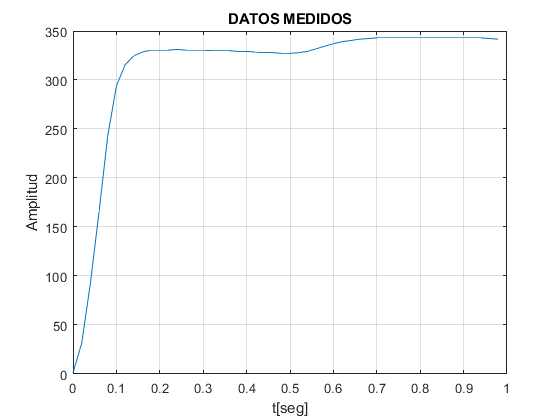

yt=y1;
%VECTOR TIEMPO DISCRETO
n=0:M-1;
%VECTOR TIEMPO CONTINUO
t=n*Ts;
%---STEP
figure("Name","datos muestreados")
plot(t,y1)
grid on
title('DATOS MEDIDOS')
xlabel('t[seg]')
ylabel('Amplitud')

### ESTIMACION DEL PROCESO

data = iddata(yt,ut,Ts);
np=2;                   %Número de polos
nz=0;                   %Número de zeros

FUNCIÓN DE TRANSFERENCIA DEL MOTOR DC 

TF1= tfest(data,np,nz);

b=TF1.Numerator;
a=TF1.Denominator;
figure("Name","RESPUESTA DEL SISTEMA A UNA ENTRADA ESCALON")
yb=1*step(TF1,t);
sistema=tf(b,a)

sistema =
 
        2.01e04
  --------------------
  s^2 + 51.9 s + 913.3
 
Continuous-time transfer function.



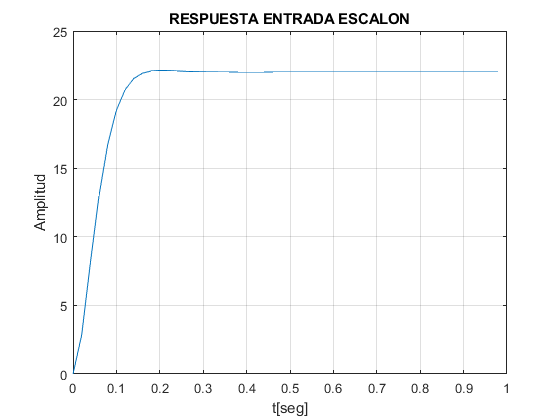

plot(t,yb)
title('RESPUESTA ENTRADA ESCALON')
xlabel('t[seg]')
ylabel('Amplitud')
grid on

obtener el periodo de muestreo

%método del diagrama de bode
[aux wgc]=margin(sistema);
%Periodo de muestreo minimo en terminos
%del margen de ganancia del diagrama de bode
Tss_min=1/(20*wgc)

Tss_min = 0.0024